## **Final Project:Noise Cancellation Approach II**

**Subject: Digital Signal Processing Laboratory**

**Teacher: Luis Arturo Montesinos Silva**

Frida Berenice Rangel García            |A01651385

Luis Arturo Dan Fong                         |A01650672

Alfredo Zhu Chen                               |A01651980

José Rubén Villicaña Ibargüengoytia |A01654347

**1.Clear the enviroment**

clear all
close all
clc

**2.Reding data and declaring parameters**

Reading noise.wav and noise_and_voice.wav files. Its sampling frequency is *Fs*=44100 Hz and its sampling period is 1/*Fs*. The sampling time *s*, time interval t and frequency interval f are declared. 

Fs=44100;                               %Sampling frequency
Ts=1/Fs;                                %Sampling period
noise= audioread('noise_delay.wav');          %Read noise data                               
voice= audioread('noise_and_voice_delay.wav');%Read noise+voice data
samples_voice=length(voice);            %Length of voice+noise
samples_noise=length(noise);            %Length of noise(shoud be equal to voice+noise) 
s=Ts*samples_noise;                     %Sampling time in seconds            
t=(0:Ts:s-Ts)';                         %time interval
f=Fs*[0:samples_noise-1]/samples_noise-Fs/2;%frequency interval

**3. Listen to the noise and noise+voice audio. **

sound(noise,Fs);                       %play noise
pause(s)                               %Pause until finish playing
sound(voice,Fs);                       %play noise+voice
pause(s)                               %Pause until finish playing

**4. Applying Fast Fourier Transform(FFT) to both signals**

noise_fourier = abs(fft(noise));        %fft magnitude of noise
voice_fourier = abs(fft(voice));        %fft magnitude of voice+noise

**5. Plots of noise in time and frequency domain in the same figure**

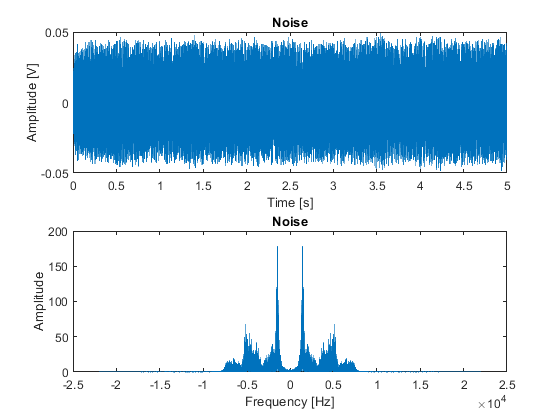

figure 
subplot(2,1,1)
plot(t,noise);                          %noise in time domain
xlabel("Time [s]")
ylabel("Amplitude [V]")
title("Noise")
subplot(2,1,2)
plot(f,fftshift(noise_fourier));        %noise in frequency domain
ylabel("Amplitude")
xlabel("Frequency [Hz]")
title("Noise")
subplot(2,1,2)

**6. Plot of noise+voice in time and frequency domain in the same figure**

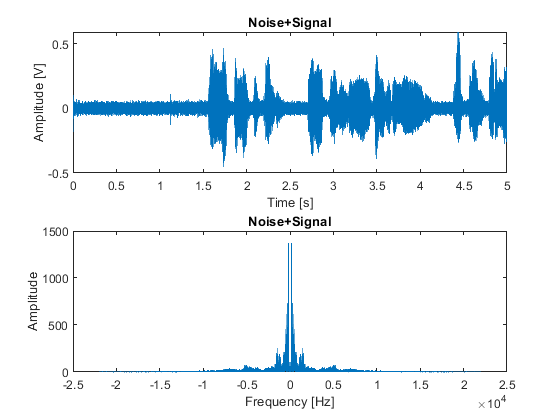

figure
subplot(2,1,1)
plot(t,voice);                          %voice+noise in time domain
xlabel("Time [s]")
ylabel("Amplitude [V]")
title("Noise+Signal")
subplot(2,1,2)
plot(f,fftshift(voice_fourier));        %voice+noise in frequency domain
xlabel("Frequency [Hz]")
ylabel("Amplitude")
title("Noise+Signal")

**7. Spectrogram of noise+voice**

Analyzing voice+noise in the frequency and time-frequency domains.

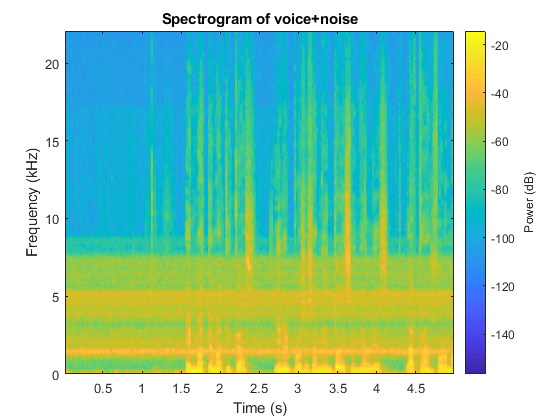

figure
pspectrum(voice,t,"spectrogram")
title("Spectrogram of voice+noise")

**8. Short Time Fourier Transform(STFT) of noise+voice signal**

Analysing the noise+voice signal in both time and frequency domain. The main idea is to divide the whole time interval into segments. Each segment of time interval contains different frequency content of the signal, so it is useful to analyse each segment separately. The Blackman window function is used to segment the signal into equal time space segment, A matrix variable *STFT* is used to allocate the frequency content of the signal with time across columns and and frequency across rows. A *for* loop used to iterate over each window and the STFT of the noise+voice signal is calculated after combining the FFT of all windows.

%% Short Time Fourier Transform 
% define the analysis and synthesis parameters
wlen=1024;
hop = wlen/8;                           %hop size
nfft = 4*wlen;                          %number of FFT points

% generate analysis and synthesis windows
anal_win = blackmanharris(wlen, 'periodic'); 
synth_win = hamming(wlen, 'periodic');

voice_len = length(voice);             % determination of the signal length 
wlen = length(anal_win);               % determination of the window length

% stft matrix size estimation and preallocation
NUP = ceil((1+nfft)/2);         % calculate the number of unique fft points
L = 1+fix((voice_len-wlen)/hop);    % calculate the number of signal frames
STFT = zeros(NUP, L);                  % preallocate the stft matrix
% STFT (via time-localized FFT)
for l = 0:L-1
    xw = voice(1+l*hop : wlen+l*hop).*anal_win; % windowing
    X = fft(xw, nfft);  % FFT
    STFT(:, 1+l) = X(1:NUP);           % update of the stft matrix
end

% calculation of the time and frequency vectors
STFT_t = (wlen/2:hop:wlen/2+(L-1)*hop)/Fs;
STFT_f = (0:NUP-1)*Fs/nfft;

**9. Noise Cancellation**

Having a threshold of the form of the noise in frequency domain, noise cancellation is performed according to the comparison of the frequency components of noise+voice signal to this value. The values in the frequency domain of noise+voice for all time segments are amplified if they are above the threshold and attenuated if they are below the threshold. 

%% Noise Cancellation
Factor = 2.5;                          %Multiplication factor                 
Th_noise = noise_fourier.*Factor;      %Noise threshold  
reduction = 0.2;                  %Noise cancellation multiplication factor
amp = 4;                               %Signal amplificaction factor

for i = 1:size(STFT,1)                 %row-time
    for j = 1:size(STFT,2)             %col-frequency
        if abs(Th_noise(i,1)) > abs(STFT(i,j))%Check if noise threshold is greater than the value
            STFT(i,j) = (STFT(i,j)).*reduction; %Noise attenuation
        else
            STFT(i,j) = (STFT(i,j)).*amp; %Voice signal amplifying
        end
    end
end

**10. Inverse Short Time Fourier Transform(ISTFT) with Weightd Overlap-Add (WOLA)**

After the noise cancellation process,the filtered signal can be obtained by applying the ISTFT with WOLA. The synthesis Hamming window function is applied after the IFFT operation before overlap-add. WOLA is used to suppress discontiuities at frame boundaries caused by nonlinear processing of the STFT. The signal is reconstructed from the STFT and the filtered signal is obtained in the variable voice_filtered.

L2 = size(STFT, 2);                 % determine the number of signal frames
wlen2 = length(synth_win);   % determine the length of the synthesis window
voice_filtered_len = wlen2+(L2-1)*hop;%estimate the length of the signal vector
voice_filtered = zeros(1, voice_filtered_len);%preallocate the signal vector
% reconstruction of the whole spectrum
if rem(nfft, 2)             
    % odd nfft excludes Nyquist point
    X = [STFT; conj(flipud(STFT(2:end, :)))];
else                        
    % even nfft includes Nyquist point
    X = [STFT; conj(flipud(STFT(2:end-1, :)))];
end
% columnwise IFFT on the STFT-matrix
xw = real(ifft(X));
xw = xw(1:wlen2, :);
% Weighted-OLA
for l = 1:L2
    voice_filtered(1+(l-1)*hop : wlen2+(l-1)*hop) = voice_filtered(1+(l-1)*hop : wlen2+(l-1)*hop) + ...
                                      (xw(:, l).*synth_win)';
end
W0 = sum(anal_win.*synth_win);         % scaling of the signal                 
voice_filtered = voice_filtered.*hop/W0;                      
t_voice_filtered = (0:voice_filtered_len-1)/Fs; % generation of the time vector

**11. Plots of result**

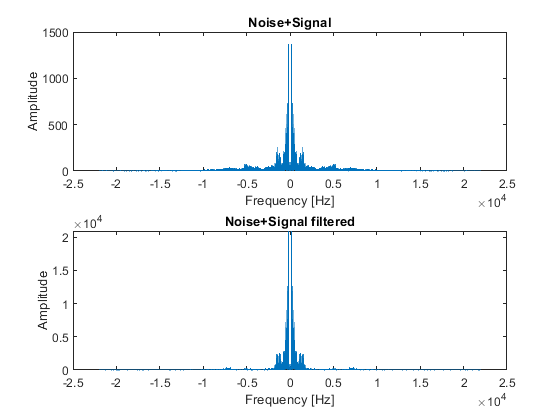

figure
subplot(2,1,1)
plot(f,fftshift(voice_fourier));         %Noise+Voice in frequency
xlabel("Frequency [Hz]")
ylabel("Amplitude")
title("Noise+Signal")
subplot(2,1,2)
plot(Fs*[0:size(voice_filtered,2)-1]/size(voice_filtered,2)-Fs/2,fftshift(abs(fft(voice_filtered))));%Noise+Voice filtered in frequency
xlabel("Frequency [Hz]")
ylabel("Amplitude")
title("Noise+Signal filtered")

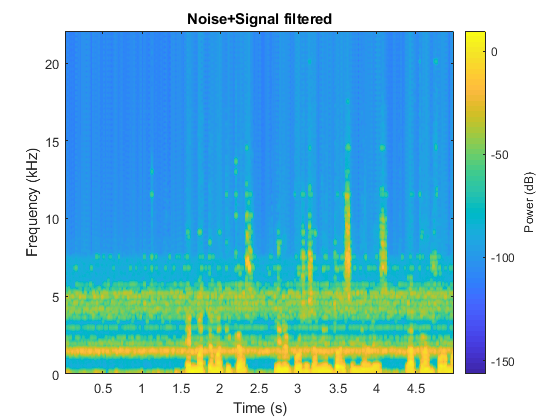


figure
pspectrum(voice_filtered,t_voice_filtered,"spectrogram")
title("Noise+Signal filtered")

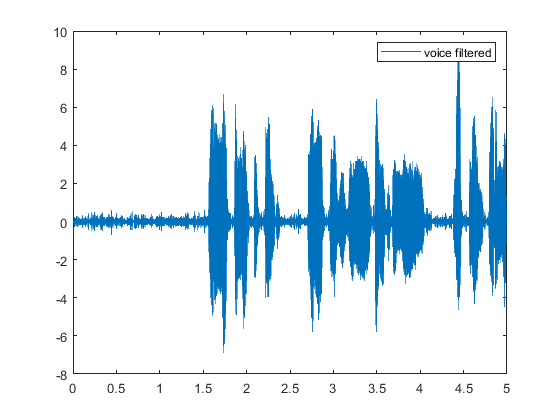

figure
plot(t_voice_filtered, voice_filtered)
legend('voice filtered')

**12. Listen  to the result audio**

sound(voice,Fs);                        %play noise+voice
pause(s)
sound(voice_filtered,Fs);               %play noise+voice filtered

**13. References**

Zhivomirov, H. (2019). Inverse Short-Time Fourier Transform (ISTFT) with MATLAB. [https://www.mathworks.com/matlabcentral/fileexchange/45577-inverse-short-time-fourier-transform-istft-with-matlab](https://www.mathworks.com/matlabcentral/fileexchange/45577-inverse-short-time-fourier-transform-istft-with-matlab)

MATLAB. (2021). ISTFT. [Inverse short-time FFT - MATLAB (mathworks.com)](https://www.mathworks.com/help/dsp/ref/dsp.istft.html)